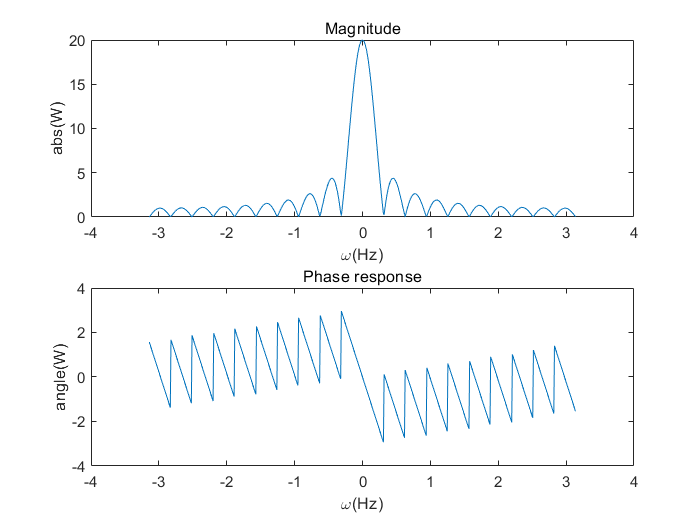

clear;clc;
N=20;
w=-pi:1/100:pi;
j=sqrt(-1);

W = (w==0).*N+(w~=0).*exp(-j*w*(N-1)/2).*sin(w*N/2)./(sin(w/2));

hold on;
subplot(2,1,1);
plot(w,abs(W));
xlabel('\omega(Hz)'),ylabel('abs(W)'),title('Magnitude');
subplot(2,1,2);
plot(w,angle(W));
xlabel('\omega(Hz)'),ylabel('angle(W)'),title('Phase response');

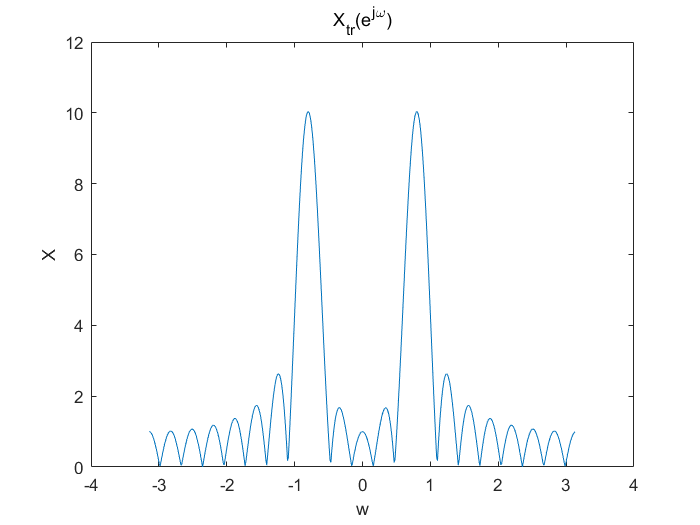

clear;close all;clc;
n=0:19;
x=cos(pi/4*n);
[X,w]=DTFT(x,512);
plot(w,abs(X));
xlabel('w'),ylabel('X'),title('X_{tr}(e^{j\omega})');

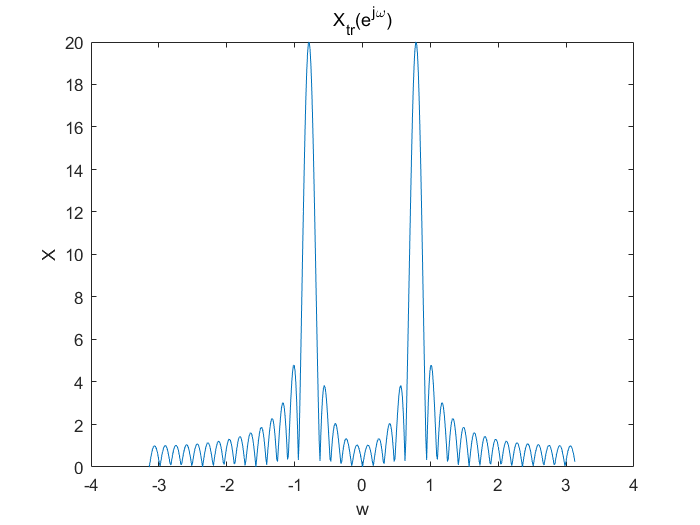

n2=0:39;
x2=cos(pi/4*n2);
[X2,w2]=DTFT(x2,512);
plot(w2,abs(X2));
xlabel('w'),ylabel('X'),title('X_{tr}(e^{j\omega})');